% =========================================================================
% PROJECT: Enhanced Radar Deinterleaving via Modular SDIF & Fusing PDWs
% Based on the paper: Hasani & Khosravi (2021)
% Architecture: Modular Design for Optimization and Easy Debugging
% =========================================================================

clc; clear; close all;

%% --- B??C 1: C?U HÌNH THAM S? ?ÀI PHÁT (EMITTER CONFIGURATION) ---
t_sim = 0.12; % Th?i gian mô ph?ng t?ng th? (120 ms)

clear emCfg; 
emCfg(1).type = 'Fixed';     emCfg(1).PRI = 157e-5;             emCfg(1).RF = 3e9;   emCfg(1).PW = 2e-6;   emCfg(1).jitter = 0;   emCfg(1).t_start = 0;      emCfg(1).p_missing = 0.15;
emCfg(2).type = 'Fixed';     emCfg(2).PRI = 157e-5;             emCfg(2).RF = 3e9;   emCfg(2).PW = 2e-6;   emCfg(2).jitter = 0;   emCfg(2).t_start = 0.0015; emCfg(2).p_missing = 0.15;
emCfg(3).type = 'Staggered'; emCfg(3).PRI = [106e-5, 112e-5, 90.8e-5]; emCfg(3).RF = 10e9;  emCfg(3).PW = 6e-6;   emCfg(3).jitter = 0;   emCfg(3).t_start = 0.0005; emCfg(3).p_missing = 0.15;
emCfg(4).type = 'Jittered';  emCfg(4).PRI = 10e-4;              emCfg(4).RF = 17e9;  emCfg(4).PW = 9e-6;   emCfg(4).jitter = 0.1; emCfg(4).t_start = 0.0030; emCfg(4).p_missing = 0.15;
emCfg(5).type = 'Fixed';     emCfg(5).PRI = 157e-5;             emCfg(5).RF = 3e9;   emCfg(5).PW = 2.4e-6; emCfg(5).jitter = 0;   emCfg(5).t_start = 0.0035; emCfg(5).p_missing = 0.15;
emCfg(6).type = 'Fixed';     emCfg(6).PRI = 159e-5;             emCfg(6).RF = 5e9;   emCfg(6).PW = 4e-6;   emCfg(6).jitter = 0;   emCfg(6).t_start = 0.0045; emCfg(6).p_missing = 0.15;

%% --- B??C 2: C?U HÌNH THAM S? THU?T TOÁN (ALGORITHM HYPERPARAMETERS) ---
algoParams.C_max = 30;       % Gi?i h?n m?c sai phân t?i ?a ?? tránh l?p vô h?n
algoParams.M0 = 1.0;         % Ng??ng t??ng ??ng kho?ng cách vân tay v?t lý (RF, PW)
algoParams.RF_0 = 3e9;       % Bán kính chu?n hóa t?n s? vô tuy?n
algoParams.PW_0 = 1e-6;      % Bán kính chu?n hóa ?? r?ng xung
algoParams.t_Bin = 1e-5;     % ?? r?ng c?a m?t ô ??m (Bin) trên Histogram
algoParams.x_emp = 2.7;      % H? s? th?c nghi?m tính hàm ng??ng t?i ?u
algoParams.k_emp = 3.5;        % H? s? suy gi?m c?a ???ng cong ng??ng ??ng

%% --- B??C 3: KÍCH HO?T ??NG C? MÔ PH?NG & TÁCH CHU?I ---

% 1. Sinh lu?ng d? li?u xung ?an xen b? nhi?u suy hao th?c t?
[pdwData, initialSDIF] = generate_pulses(emCfg, t_sim);

% 2. Ch?y thu?t toán vòng l?p sai phân SDIF & Tìm ki?m ?a tham s? g?c
[separated_sequences, extracted_flags] = sdif_deinterleave(pdwData, algoParams);


--- STARTING DEINTERLEAVING LOOP ---

[M?c sai phân C=1] Các PRI ti?m n?ng (PRI_p) v??t ng??ng:
  + Non-Jittered PRIs (ms): 0.0050

[M?c sai phân C=2] Các PRI ti?m n?ng (PRI_p) v??t ng??ng:
  + Non-Jittered PRIs (ms): 0.0150

[M?c sai phân C=3] Các PRI ti?m n?ng (PRI_p) v??t ng??ng:
  + Non-Jittered PRIs (ms): 0.0250  0.1350  0.1850  0.2850  0.3850  0.4850  0.7850  0.8350  0.8850  0.9850  1.0350  1.2350  1.4350
  + Jittered PRIs (ms):     0.2150  0.2350  0.3150  0.3350

[M?c sai phân C=4] Các PRI ti?m n?ng (PRI_p) v??t ng??ng:
  + Non-Jittered PRIs (ms): 0.2150  0.2550  0.3350  0.7450  0.7850  0.8750  1.0350  1.1750  1.2050  1.4350  1.5150  1.6950  2.1750
  + Jittered PRIs (ms):     0.3650  0.3850  0.4050  0.4450  0.4550  0.4850  0.4950  0.5250  0.5350  0.5550  0.5750  0.5950  0.6150  0.6350  0.6550  0.6850  0.7050  0.8250  0.8350  0.9250  0.9350  0.9450  0.9550  1.1250  1.1350  1.2450  1.2550  1.3850  1.3950
>> Successfully extracted 1 Emitter! (C=4, PRI=0.8250 ms, Pulses=75)

[M?c s


% 3. Kh?i h?u x? lý cao c?p: G?p các m?nh sóng hài và b?o v? ?ài ??ng kênh
mergeParams.rf_merge_tol = 0.5e9;   % Dung sai th?t ch?t vân tay RF (0.5 GHz)
mergeParams.pw_merge_tol = 0.5e-6;  % Dung sai th?t ch?t vân tay PW (0.5 us)
mergeParams.pri_ratio_tol = 0.08;   % Sai s? t? l? sóng hài cho phép (8%)
final_sequences = merge_sequences(pdwData, separated_sequences, mergeParams);


--- STARTING ADVANCED HARMONIC SEQUENCE MERGING ---
--- K?T THÚC H?U X? LÝ CAO C?P: Phân tách thành 7 ngu?n phát hoàn ch?nh ---




%% --- B??C 4: XU?T BÁO CÁO KI?M TOÁN & ?? TH? TR?C QUAN ---
export_results(pdwData, final_sequences, extracted_flags);


>> ?Ã ??NG B? PDW_TABLE TH?C T? (Hi?n th? 20 xung ??u tiên):
    TOA_ms    RF_GHz    PW_us     Emitter_ID
    ______    ______    ______    __________

       0.5    9.0281    5.8285        3     
       1.5    3.2531    1.7883        2     
      1.56    10.057    6.2536        3     
      1.57    3.1321    1.9708        1     
      2.68    9.9496    5.7079        3     
         3    16.194    9.6337        4     
      3.07     2.971    2.0281        2     
      3.14    2.7899    2.1551        1     
       3.5     2.977    2.3476        5     
    3.9638    15.676    9.8261        4     
      4.64    2.8454    1.9636        2     
     4.648      10.9    5.7408        3     
      4.71    3.0929    1.9531        1     
    4.9713    16.114    8.8022        4     
      5.07     2.895    2.4091        5     
     5.768    10.274    5.7614      


--- STARTING VISUAL VERIFICATION PLOTS ---


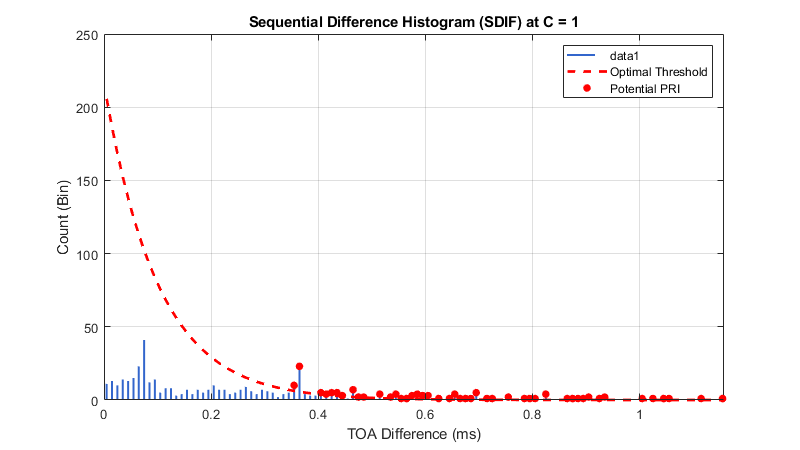

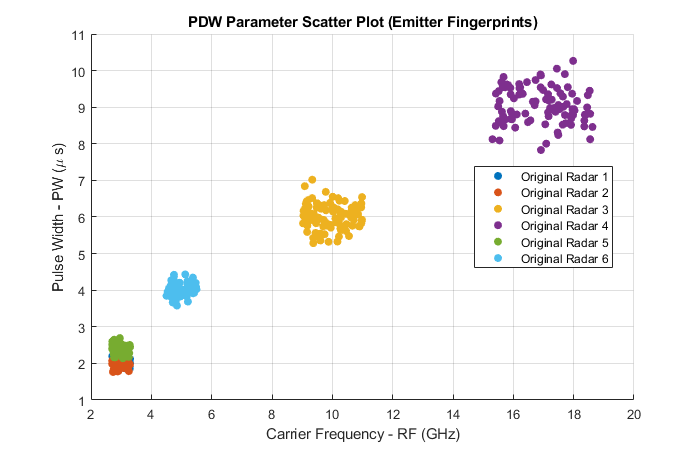

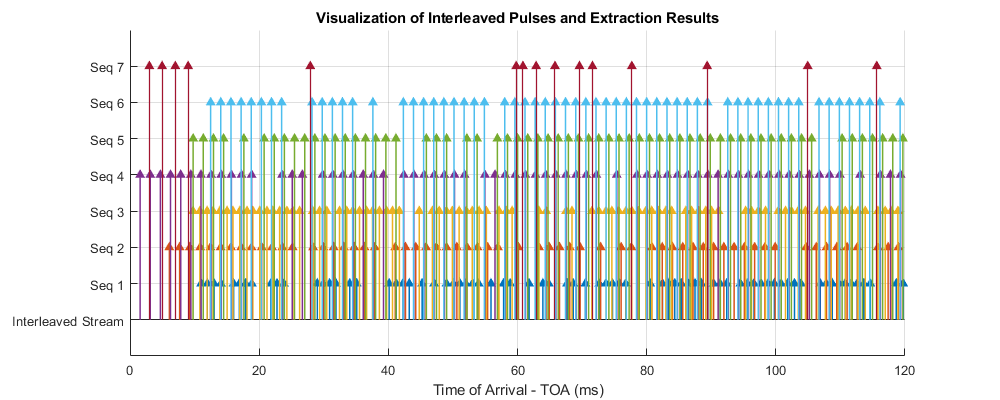

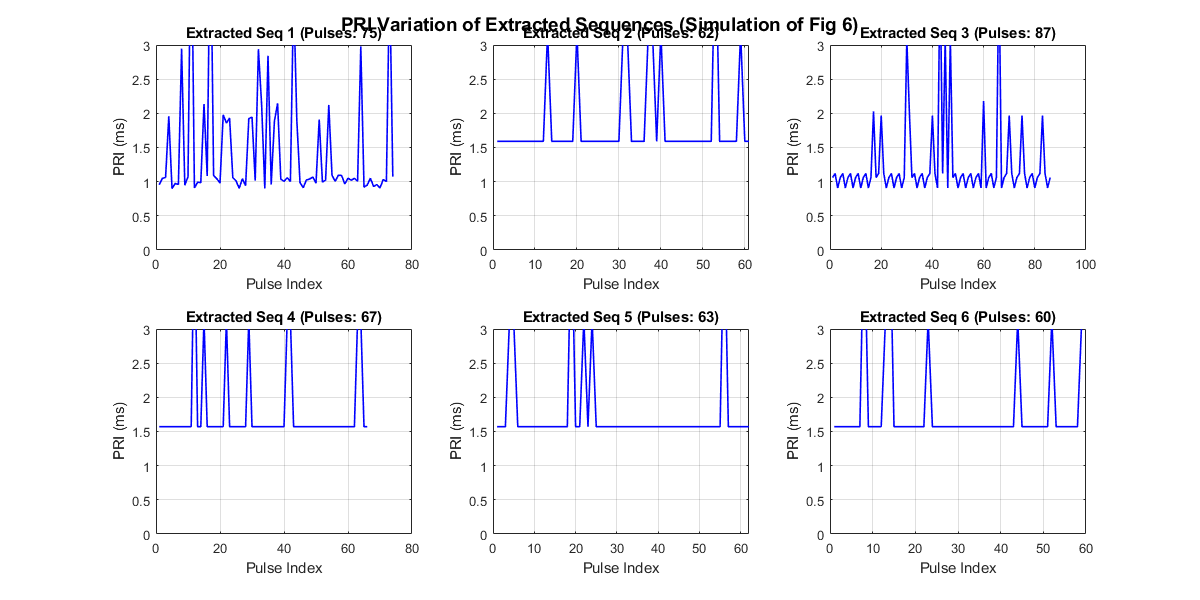

plot_results(pdwData, final_sequences, initialSDIF, length(emCfg));